# Scatter simulation

## parameter setting

material_air = 1;
material_water = 2;
material_bone = 3;    % 注意in文件中material文件的顺序
voel_num = 512;
voxel_size = 0.042; % cm
sdd = 114;
sod = 61.3;
nu = 256; % number of pixels in the image: Nx
nv = 256; % Ny 
du = 0.042*4; % cm
dv = 0.042*4;
delta_z = 6.8; % 实际射线源偏移(cm)
delta_zdetector = 2*delta_z*(1+(sdd-sod)/sod);
delta_nv = ceil(delta_zdetector/dv); % 对应探测器的扩大
MCparam = load_MCGPU_param('E:\firstImaging\MCGPU_matlab\MCGPU_MATLAB_sample.in');

spec file not found, please reload in your script!


MCparam.sdd = sdd;
MCparam.sod = sod;
MCparam.total_histories = nu*(nv+delta_nv)*5*10000;
MCparam.aperture(:) = -1; % cone beam; 0 is pencil beam
MCparam.source_pos = [voel_num*voxel_size/2;voel_num*voxel_size/2-sod;voel_num*voxel_size/2-delta_z]; 
MCparam.det_size = [nu*du;nu*du+delta_zdetector]; 
MCparam.dummy_num_pixels = int32([nu;nv+delta_nv]);
try
    MCparam.spec = parse_spectrum_file('E:\318\MC\100kVp_0.5mmCu_8.0mmAL.spec');
    fprintf('spec file is successfully loaded!');
catch
    error('Spec file not found, please reload');
end

spec file is successfully loaded!

MCparam.num_projections =4;
MCparam.D_angle = 90; % ANGLE BETWEEN PROJECTIONS [degrees] (360\num_projections for full CT)

## initialize MCGPU

MCGPU_mex('init', MCparam); % MCparam 里的参数修改后都要进行初始化



     *****************************************************************************
     ***         MC-GPU, version 1.3 (http://code.google.com/p/mcgpu/)         ***
     ***                                                                       ***
     ***  A. Badal and A. Badano, "Accelerating Monte Carlo simulations of     *** 
     ***  photon transport in a voxelized geometry using a massively parallel  *** 
     ***  Graphics Processing Unit", Medical Physics 36, pp. 4878鈥?880 (2009)  ***
     ***                                                                       ***
     ***                     Andreu Badal (Andreu.Badal-Soler@fda.hhs.gov)     ***
     *****************************************************************************

****** Code execution started on: Tue Aug  6 14:35:46 2024



             *** CUDA SIMULATION IN THE GPU ***

    -- INITIALIZATION phase:
       3D voxel dose deposition tally DISABLED.
       Rotations from the input direction to +Y [deg]: rotZ 

## load vox file and run MCGPU

voxel_data = parse_vox_file('E:\318\MC\vox_vol_interconvert\runs\waterNew.vox');

       Total number of voxels read: 134217728


fprintf('vox file is successfully loaded!');

vox file is successfully loaded!

[prime,compton,rayleign,Mscatter]=MCGPU_mex('run',voxel_data); 

       Number of voxels in the input geometry file: 512 x 512 x 512 =  134217728
       Size of the input voxels: 0.042000 x 0.042000 x 0.042000 cm  (voxel volume=0.000074 cm^3)
       Voxel bounding box size: 21.504000 x 21.504000 x 21.504000 cm
       The voxel dose tally ROI covers only a fraction of the voxelized phantom: the dose to voxels outside the ROI will not be tallied.

    -- Initializing the voxel material and density vector (1024.000000 Mbytes)...
       Total CPU memory allocated for voxels vector and data structures = 1031.045532 Mbytes

    -- Reading the material data files (MAX_MATERIALS=20):
         Mat 1: File '.\material\air__5-120keV.mcgpu.gz                       '
                Nominal density = 0.001205 g/cm^3; Max density in voxels = 0.001205 g/cm^3
                Number of energy values in the mean free path database: 23001.
                Linear interpolation data correctly allocated (10.704506 Mbytes)
                Lowest energy first bin = 5000.00

## clean up

MCGPU_mex('clear');

## summed scatter and total signals

scatter = compton + rayleign+ Mscatter;
total = prime + scatter; 

## show images

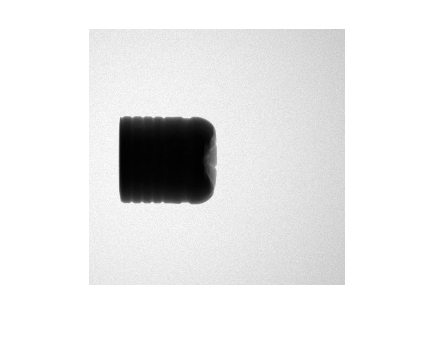

figure;
for idx = 1:MCparam.num_projections
    imshow(prime(:,delta_nv+1:end,idx),[]);
end

## save images 

filename = 'water';
for idx = 1:MCparam.num_projections
    filePath = sprintf('E:/firstImaging/test/%s_%d.raw', filename, idx);
%   fwrite(fid,[prime(:,delta_nv+1:end,idx),scatter(:,delta_nv+1:end,idx)],'float32');  %[primary, scatter]
    proj = [total(:,delta_nv+1:end,idx),prime(:,delta_nv+1:end,idx),scatter(:,delta_nv+1:end,idx)]; %[total, primary, scatter]
    XuWriteRaw(filePath,proj,'float32');
end

% save('MCGPU_water_20240718','total','prime','scatter'); % save as .mat file if you want


# Scatter correction for 318 CT

% load("MCGPU_water_20240718.mat");
folder = 'F:\318-DATA\20240715-WATER2';
filenames = dir([folder '\*.raw']);
file_length = length(filenames)-1; % 800
projs = zeros(1024,1024,file_length);
for idx = 1:file_length
    projs(:,:,idx) = XuReadRaw([folder '\' filenames(idx+1).name],[1024 1024 1],'uint16');
end
projs_resized = imresize3(projs,[512 512 file_length]); % accelerate

## calculate primary of real projs

pri_r = resizeAndInterp(prime(:,delta_nv+1:end,:), 256, 256, 800);
total_r = resizeAndInterp(total(:,delta_nv+1:end,:), 256, 256, 800);
p = 1 - (1 - (pri_r ./ total_r));
p = imgaussfilt(p, 15);
p = imresize3(p,[512 512 file_length]);
for idx = 1:file_length
    p(:,:,idx) = rot90(p(:,:,idx), -1);
end
pri_real = projs_resized .* p;

## Save projs without scatters

MgWriteTiff('E:\firstImaging\test\pri_real.tif',pri_real);

# Generate vox file

## binarize image

img_rec = MgReadTiff('E:\318\MC\waterNew\rec\rec_waterNew.tif');
img_rec = flip(img_rec,3);
img_rec = flip(img_rec,2);
[x,y,z] = size(img_rec);
img_bi = zeros(x,y,z);
for i = 1:z
    img_rec_i = img_rec(:,:,i);
    img_rec_i(img_rec_i >= -200) = 1;
    img_rec_i(img_rec_i < -200) = 0;
    img_rec_i(:,1:90) = 0;
    img_bi(:,:,i) = img_rec_i;
end
% MgWriteTiff('E:\firstImaging\test\bi.tif',img_bi_n);

## fill density

density_air = 0.00120479;
density_water = 1.0;
density_bone = 1.75;
% img_bi = MgReadTiff("E:\318\MC\vox_vol_interconvert\Data\waterNew.tif");
% % 原来用于linux的，处理CT图时要先进行水平翻转和逆时针90度旋转
% img_bi = flip(img_bi, 2);
% img_bi = permute(img_bi, [2, 1, 3]); % x，y转置


[x,y,z] = size(img_bi);
voxel_data.num_voxels = [x;y;z];
voxel_data.voxel_size = [0.042;0.042;0.042];
voxel_data.density_max = ones(20, 1, 'single') * -999;
voxel_data.material = ones(x, y, z, 'single');
voxel_data.density = ones(x, y, z, 'single') * density_air;
voxel_data.density_max(material_air) = density_air;
voxel_data.density_max(material_water) = density_water;
voxel_data.density_max(material_bone) = density_bone;
for dz = 1:z
    for dy = 1:y
        for dx = 1:x
            if img_bi(dx,dy,dz) == 1
                voxel_data.material(dx,dy,dz) = material_water;
                voxel_data.density(dx,dy,dz) = density_water;
            end
            if img_bi(dx,dy,dz) ~= 1 && img_bi(dx,dy,dz) ~= 0
                voxel_data.material(dx,dy,dz) = material_bone;
                voxel_data.density(dx,dy,dz) = img_bi(dx,dy,dz);
            end
        end
    end
end

% voxel_data = parse_vox_file('E:\318\MC\vox_vol_interconvert\runs\halfwater_NEW_100.vox');
[p,c,r,s] = MCGPU_mex('run',voxel_data);

       Number of voxels in the input geometry file: 512 x 512 x 512 =  134217728
       Size of the input voxels: 0.042000 x 0.042000 x 0.042000 cm  (voxel volume=0.000074 cm^3)
       Voxel bounding box size: 21.504000 x 21.504000 x 21.504000 cm
       The voxel dose tally ROI covers only a fraction of the voxelized phantom: the dose to voxels outside the ROI will not be tallied.

    -- Initializing the voxel material and density vector (1024.000000 Mbytes)...
       Total CPU memory allocated for voxels vector and data structures = 1031.045532 Mbytes

    -- Reading the material data files (MAX_MATERIALS=20):
         Mat 1: File '.\material\air__5-120keV.mcgpu.gz                       '
                Nominal density = 0.001205 g/cm^3; Max density in voxels = 0.001205 g/cm^3
                Number of energy values in the mean free path database: 23001.
                Linear interpolation data correctly allocated (10.704506 Mbytes)
                Lowest energy first bin = 5000.00

MCGPU_mex('clear');

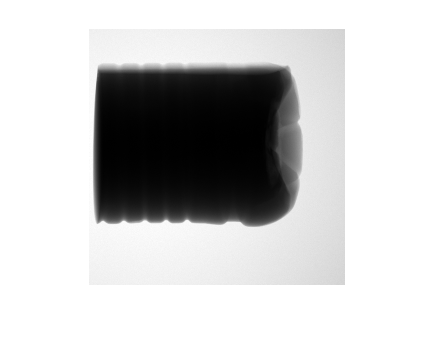

figure;
for i=1:MCparam.num_projections
    imshow(p(:,delta_nv+1:end,i),[]);
    pause(0.5);
end

% p_re = p(:,delta_nv+1:end,:);
% p_re = rot90(p_re,-1);
% MgWriteTiff('E:\firstImaging\test\p_pig.tif',p_re);